% Load your data
load("orientation_data.mat");

% Extract relevant columns
channelsData = orientationData(2:end, 2:end);
labels = repmat({'normal'}, size(channelsData, 1), 1);

% Convert cell array to numeric array for channels data
channelsDataNumeric = cell2mat(channelsData);

% Create a table with columns for channels and labels
tableData = table(channelsDataNumeric(:, 1), channelsDataNumeric(:, 2), channelsDataNumeric(:, 3), labels, 'VariableNames', {'channel1', 'channel2', 'channel3', 'label'});

% Display the resulting table
disp(tableData);

    channel1    channel2    channel3      label   
    ________    ________    ________    __________

        0           3           47      {'normal'}
       -1           4           47      {'normal'}
        0           5           47      {'normal'}
        0           4           46      {'normal'}
        0           4           46      {'normal'}
        0           4           46      {'normal'}
        0           4           46      {'normal'}
        0           5           46      {'normal'}
        0           4           46      {'normal'}
        0           4           46      {'normal'}
       -1           4           46      {'normal'}
       -1           4           46      {'normal'}
       -1           4           46      {'normal'}
       -1           3           46      {'normal'}
       -1           3           46      {'norma

sFE = signalTimeFeatureExtractor(SampleRate=10,Mean=true,RMS=true,PeakValue=true,FrameSize=10,FrameOverlapLength=3,StandardDeviation=true,ShapeFactor=true);
vikas1=extract(sFE,tableData.channel1)

vikas1 =    -0.1000    0.3162    0.3162    3.1623    1.0000
   -0.7000    0.9487    0.6749    1.3553    2.0000
    0.4000    3.3166    3.4705    1.3819    7.0000
   -0.9000    3.7815    3.8715    1.3040    7.0000
    0.6000    1.1832    1.0750    1.1832    2.0000
   -0.8000    2.7203    2.7406    1.3601    6.0000
    2.1000    3.3912    2.8067    1.1694    6.0000
    9.1000    9.6695    3.4464    1.0626   13.0000
    8.2000    9.0885    4.1312    1.1083   13.0000
    2.7000    4.0373    3.1640    1.2234    7.0000


vikas2=extract(sFE,tableData.channel2)

vikas2 =     4.1000    4.1352    0.5676    1.0086    5.0000
    3.4000    3.5777    1.1738    1.0523    5.0000
    0.8000    2.4083    2.3944    1.3380    5.0000
   -2.3000    3.4496    2.7101    1.2776    6.0000
   -1.1000    3.8341    3.8715    1.0954    6.0000
    2.5000    3.1780    2.0683    1.1771    5.0000
    0.4000    1.1832    1.1738    1.1832    2.0000
    2.5000    4.9092    4.4535    1.4026    9.0000
    0.4000    4.9800    5.2324    1.2450    9.0000
   -1.3000    2.3022    2.0028    1.3542    4.0000


vikas3=extract(sFE,tableData.channel3)

vikas3 =    46.3000   46.3023    0.4830    1.0000   47.0000
   46.3000   46.3044    0.6749    1.0001   48.0000
   36.6000   38.1130   11.2071    1.0413   48.0000
   22.4000   24.0000    9.0823    1.0714   33.0000
   36.4000   37.7439   10.5219    1.0369   60.0000
   85.1000   89.7402   30.0239    1.0545  120.0000
   58.5000   68.0977   36.7431    1.1641  120.0000
  -39.3000   61.0254   49.2117    1.1989  115.0000
  -56.6000   68.2246   40.1530    1.2054  115.0000
   -1.9000    4.7434    4.5814    1.8974   14.0000


feature_data=horzcat(vikas1,vikas2,vikas3);
% Add 'labels' column with 'normal' values
feature_data = [feature_data, repmat("normal", size(feature_data, 1), 1)]

feature_data = 64x16 string array
    "-0.1"     "0.3162278"    "0.3162278"    "3.162278"    "1"     "4.1"      "4.135215"    "0.5676462"    "1.008589"    "5"     "46.3"      "46.30227"    "0.4830459"    "1.000049"    "47"     "normal"
    "-0.7"     "0.9486833"    "0.6749486"    "1.355262"    "2"     "3.4"      "3.577709"    "1.173788"     "1.052267"    "5"     "46.3"      "46.30443"    "0.6749486"    "1.000096"    "48"     "normal"
    "0.4"      "3.316625"     "3.470511"     "1.381927"    "7"     "0.8"      "2.408319"    "2.394438"     "1.337955"    "5"     "36.6"      "38.11299"    "11.20714"     "1.041339"    "48"     "normal"
    "-0.9"     "3.781534"     "3.871549"     "1.303977"    "7"     "-2.3"     "3.449638"    "2.710064"     "1.277644"    "6"     "22.4"      "24"          "9.082339"     "1.071429"    "33"     "normal"
    "0.6"      "1.183216"     "1.074968"     "1.183216"    "2"     "-1.1"     "3.834058"    "3.871549"     "1.095445"    "6"     "36.4"      "37.74387"    "10

rng(0) % set for reproducibility
idx = cvpartition(feature_data(:,16), 'holdout', 0.1)

idx = Hold-out cross validation partition
   NumObservations: 64
       NumTestSets: 1
         TrainSize: 58
          TestSize: 6
          IsCustom: 0

featureTrain = feature_data(idx.training, :)

featureTrain = 58x16 string array
    "-0.1"     "0.3162278"    "0.3162278"    "3.162278"    "1"     "4.1"      "4.135215"    "0.5676462"    "1.008589"    "5"     "46.3"      "46.30227"    "0.4830459"    "1.000049"    "47"     "normal"
    "-0.7"     "0.9486833"    "0.6749486"    "1.355262"    "2"     "3.4"      "3.577709"    "1.173788"     "1.052267"    "5"     "46.3"      "46.30443"    "0.6749486"    "1.000096"    "48"     "normal"
    "0.4"      "3.316625"     "3.470511"     "1.381927"    "7"     "0.8"      "2.408319"    "2.394438"     "1.337955"    "5"     "36.6"      "38.11299"    "11.20714"     "1.041339"    "48"     "normal"
    "-0.9"     "3.781534"     "3.871549"     "1.303977"    "7"     "-2.3"     "3.449638"    "2.710064"     "1.277644"    "6"     "22.4"      "24"          "9.082339"     "1.071429"    "33"     "normal"
    "0.6"      "1.183216"     "1.074968"     "1.183216"    "2"     "-1.1"     "3.834058"    "3.871549"     "1.095445"    "6"     "36.4"      "37.74387"    "10

featureTest = feature_data(idx.test, :)

featureTest = 6x16 string array
    "4.6"      "4.878524"    "1.712698"    "1.060549"    "7"     "-0.7"     "1.048809"    "0.8232726"    "1.498298"    "2"     "-119.6"    "121.5376"    "22.78499"    "1.016201"    "151"    "normal"
    "4"        "4.242641"    "1.490712"    "1.06066"     "6"     "-1.4"     "2.569047"    "2.270585"     "1.835033"    "5"     "-60.4"     "156.694"     "152.406"     "1.00188"     "172"    "normal"
    "-13.2"    "15.48548"    "8.534896"    "1.173142"    "24"    "-21.7"    "26.77499"    "16.53313"     "1.23387"     "43"    "71.2"      "72.23157"    "12.82186"    "1.014488"    "86"     "normal"
    "-2.9"     "5.375872"    "4.771443"    "1.378429"    "11"    "4"        "12.60952"    "12.60511"     "1.3706"      "26"    "49.1"      "56.46326"    "29.38802"    "1.140672"    "74"     "normal"
    "7.6"      "8.221922"    "3.306559"    "1.081832"    "14"    "-2.6"     "6.164414"    "5.891614"     "1.185464"    "11"    "-5"        "26.66458"    "27.60837"    "1.28

featureNormal = featureTrain(featureTrain(:,end)=='normal', :)

featureNormal = 58x16 string array
    "-0.1"     "0.3162278"    "0.3162278"    "3.162278"    "1"     "4.1"      "4.135215"    "0.5676462"    "1.008589"    "5"     "46.3"      "46.30227"    "0.4830459"    "1.000049"    "47"     "normal"
    "-0.7"     "0.9486833"    "0.6749486"    "1.355262"    "2"     "3.4"      "3.577709"    "1.173788"     "1.052267"    "5"     "46.3"      "46.30443"    "0.6749486"    "1.000096"    "48"     "normal"
    "0.4"      "3.316625"     "3.470511"     "1.381927"    "7"     "0.8"      "2.408319"    "2.394438"     "1.337955"    "5"     "36.6"      "38.11299"    "11.20714"     "1.041339"    "48"     "normal"
    "-0.9"     "3.781534"     "3.871549"     "1.303977"    "7"     "-2.3"     "3.449638"    "2.710064"     "1.277644"    "6"     "22.4"      "24"          "9.082339"     "1.071429"    "33"     "normal"
    "0.6"      "1.183216"     "1.074968"     "1.183216"    "2"     "-1.1"     "3.834058"    "3.871549"     "1.095445"    "6"     "36.4"      "37.74387"    "1

labelsNormal = ones(size(featureNormal, 1), 1)% Assign a label, e.g., 1, for the normal class

labelsNormal =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


% Extract features and labels
X_train =double(featureNormal(:, 1:end-1)) % Features

X_train =    -0.1000    0.3162    0.3162    3.1623    1.0000    4.1000    4.1352    0.5676    1.0086    5.0000   46.3000   46.3023    0.4830    1.0000   47.0000
   -0.7000    0.9487    0.6749    1.3553    2.0000    3.4000    3.5777    1.1738    1.0523    5.0000   46.3000   46.3044    0.6749    1.0001   48.0000
    0.4000    3.3166    3.4705    1.3819    7.0000    0.8000    2.4083    2.3944    1.3380    5.0000   36.6000   38.1130   11.2071    1.0413   48.0000
   -0.9000    3.7815    3.8715    1.3040    7.0000   -2.3000    3.4496    2.7101    1.2776    6.0000   22.4000   24.0000    9.0823    1.0714   33.0000
    0.6000    1.1832    1.0750    1.1832    2.0000   -1.1000    3.8341    3.8715    1.0954    6.0000   36.4000   37.7439   10.5219    1.0369   60.0000
   -0.8000    2.7203    2.7406    1.3601    6.0000    2.5000    3.1780    2.0683    1.1771    5.0000   85.1000   89.7402   30.0239    1.0545  120.0000
    2.1000    3.3912    2.8067    1.1694    6.0000    0.4000    1.1832    1.1738    

y_train = labelsNormal % Labels

y_train =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


## **Detect Anomalies with One-Class SVM**

Support Vector Machines are powerful classifiers, and the variant that trains on only the normal data is used here.. This model works well for identifying abnormalities that are "far" from the normal data. Train a one-class SVM model using the `fitcsvm `function and the data for normal conditions.

% Train SVM model using fitcsvm
svmModel = fitcsvm(X_train, y_train, 'Standardize', true, 'KernelFunction', 'linear');

% Display SVM model details
disp(svmModel);

  ClassificationSVM
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: 1
           ScoreTransform: 'none'
          NumObservations: 58
                    Alpha: [58x1 double]
                     Bias: 9.2593e-14
         KernelParameters: [1x1 struct]
                       Mu: [4.1241 9.0493 5.2408 1.2450 13.4828 -2.6293 9.8098 6.3010 1.2471 15.4138 20.5586 76.8077 33.4884 1.0861 99.1724]
                    Sigma: [9.2643 8.2921 5.1421 0.3173 11.3311 10.2408 9.0321 5.8910 0.3038 12.9575 69.9605 44.7063 42.8175 0.1435 49.5595]
           BoxConstraints: [58x1 double]
          ConvergenceInfo: [1x1 struct]
          IsSupportVector: [58x1 logical]
                   Solver: 'SMO'


  Properties, Methods



featureNormal_test = featureTest(featureTest(:,end)=='normal', :)

featureNormal_test = 6x16 string array
    "4.6"      "4.878524"    "1.712698"    "1.060549"    "7"     "-0.7"     "1.048809"    "0.8232726"    "1.498298"    "2"     "-119.6"    "121.5376"    "22.78499"    "1.016201"    "151"    "normal"
    "4"        "4.242641"    "1.490712"    "1.06066"     "6"     "-1.4"     "2.569047"    "2.270585"     "1.835033"    "5"     "-60.4"     "156.694"     "152.406"     "1.00188"     "172"    "normal"
    "-13.2"    "15.48548"    "8.534896"    "1.173142"    "24"    "-21.7"    "26.77499"    "16.53313"     "1.23387"     "43"    "71.2"      "72.23157"    "12.82186"    "1.014488"    "86"     "normal"
    "-2.9"     "5.375872"    "4.771443"    "1.378429"    "11"    "4"        "12.60952"    "12.60511"     "1.3706"      "26"    "49.1"      "56.46326"    "29.38802"    "1.140672"    "74"     "normal"
    "7.6"      "8.221922"    "3.306559"    "1.081832"    "14"    "-2.6"     "6.164414"    "5.891614"     "1.185464"    "11"    "-5"        "26.66458"    "27.60837"  

labelsNormal_test = ones(size(featureNormal_test, 1), 1)% Assign a label, e.g., 1, for the normal class

labelsNormal_test =      1
     1
     1
     1
     1
     1


% Extract features and labels
X_test =double(featureNormal_test(:, 1:end-1)) % Features

X_test =     4.6000    4.8785    1.7127    1.0605    7.0000   -0.7000    1.0488    0.8233    1.4983    2.0000 -119.6000  121.5376   22.7850    1.0162  151.0000
    4.0000    4.2426    1.4907    1.0607    6.0000   -1.4000    2.5690    2.2706    1.8350    5.0000  -60.4000  156.6940  152.4060    1.0019  172.0000
  -13.2000   15.4855    8.5349    1.1731   24.0000  -21.7000   26.7750   16.5331    1.2339   43.0000   71.2000   72.2316   12.8219    1.0145   86.0000
   -2.9000    5.3759    4.7714    1.3784   11.0000    4.0000   12.6095   12.6051    1.3706   26.0000   49.1000   56.4633   29.3880    1.1407   74.0000
    7.6000    8.2219    3.3066    1.0818   14.0000   -2.6000    6.1644    5.8916    1.1855   11.0000   -5.0000   26.6646   27.6084    1.2820   53.0000
    9.6000    9.6333    0.8433    1.0035   11.0000   -2.5000    2.8107    1.3540    1.1243    4.0000  -98.5000  135.7339   98.4403    1.0167  175.0000


y_test = labelsNormal_test % Labels

y_test =      1
     1
     1
     1
     1
     1


Validate the trained SVM model by using test data, which contains both normal and anomalous data.

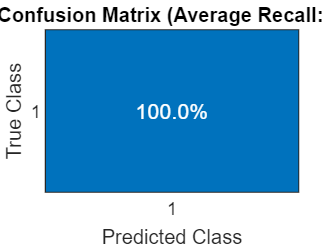

figure;
confMat = confusionchart(y_test, y_pred, 'Title', 'Confusion Matrix');
confMat.Normalization = 'row-normalized';

% Display recall in the title
recalls = diag(confMat.NormalizedValues);
avgRecall = mean(recalls);
title(['Confusion Matrix (Average Recall: ' num2str(avgRecall) ')']);